clear all
clc

%symbols
syms m J c k
syms a1 a2 s1 s2
syms M C K T F Y 
syms y1 y2 y_dot_1 y_dot_2 y_ddot_1 y_ddot_2 F1 F2 
syms theta
syms s

%%Setup of matrix
% m=20;                    % [kg], moving mass in y
% k = 2e4;                 %[Nm/rad],  rotational stiffness
% c = 2;                   %[Nms/rad], rotational damping
% J = 0.1;                 %[kgm2], moment of inertia of the stage
% a1 = 250e-3;             
% a2 = 250e-3;             
% s1 = 25e-3;              
% s2 = 25e-3;             


M=[m 0;
   0 J]

$$M = \left(\begin{array}{cc} m & 0\\ 0 & J \end{array}\right)$$

C=[0 0
   0 c]

$$C = \left(\begin{array}{cc} 0 & 0\\ 0 & c \end{array}\right)$$

K=[0 0;
   0 k]

$$K = \left(\begin{array}{cc} 0 & 0\\ 0 & k \end{array}\right)$$

F=[1 1;
   -a1 a2]

$$F = \left(\begin{array}{cc} 1 & 1\\ -a_{1} & a_{2} \end{array}\right)$$

T=[1 -s1;
   1 s2]

$$T = \left(\begin{array}{cc} 1 & -s_{1}\\ 1 & s_{2} \end{array}\right)$$




y = [y1; y2]

$$y = \left(\begin{array}{c} y_{1}\\ y_{2} \end{array}\right)$$

y_d = [y_dot_1; y_dot_2]

$$y\_d = \left(\begin{array}{c} {\dot{y}}_{1}\\ {\dot{y}}_{2} \end{array}\right)$$

y_dd = [y_ddot_1; y_ddot_2]

$$y\_dd = \left(\begin{array}{c} {\ddot{y}}_{1}\\ {\ddot{y}}_{2} \end{array}\right)$$


y_l = y;
yd_l = [y1*s; y2*s];
ydd_l = [y1*s^2; y2*s^2];

F_y = [F1; F2]

$$F\_y = \left(\begin{array}{c} F_{1}\\ F_{2} \end{array}\right)$$


Finv = inv(F)

$$Finv = \left(\begin{array}{cc} \frac{a_{2}}{a_{1}+a_{2}} & -\frac{1}{a_{1}+a_{2}}\\ \frac{a_{1}}{a_{1}+a_{2}} & \frac{1}{a_{1}+a_{2}} \end{array}\right)$$

Tinv = inv(T)

$$Tinv = \left(\begin{array}{cc} \frac{s_{2}}{s_{1}+s_{2}} & \frac{s_{1}}{s_{1}+s_{2}}\\ -\frac{1}{s_{1}+s_{2}} & \frac{1}{s_{1}+s_{2}} \end{array}\right)$$



M_mod = inv(F)*M*inv(T)

$$M\_mod = \begin{array}{l} \left(\begin{array}{cc} \frac{J}{\sigma_{1}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{1}} & \frac{a_{2}\,m\,s_{1}}{\sigma_{1}}-\frac{J}{\sigma_{1}}\\ \frac{a_{1}\,m\,s_{2}}{\sigma_{1}}-\frac{J}{\sigma_{1}} & \frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

C_mod = inv(F)*C*inv(T)

$$C\_mod = \left(\begin{array}{cc} \frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & -\frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}\\ -\frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & \frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} \end{array}\right)$$

K_mod = inv(F)*K*inv(T) 

$$K\_mod = \left(\begin{array}{cc} \frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & -\frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}\\ -\frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & \frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} \end{array}\right)$$


%[X, e] = polyeig(K_mod, C_mod, M_mod)
[X e] = eig(M_mod^-1*K_mod)

$$X = \left(\begin{array}{cc} 1 & -\frac{s_{1}}{s_{2}}\\ 1 & 1 \end{array}\right)$$

$$e = \left(\begin{array}{cc} 0 & 0\\ 0 & \frac{k}{J} \end{array}\right)$$


MM = X'*M_mod*X

$$MM = \begin{array}{l} \left(\begin{array}{cc} \sigma_{4}+\sigma_{3}+\sigma_{6}+\sigma_{5} & \sigma_{4}-\frac{s_{1}\,\left(\sigma_{3}+\sigma_{5}\right)}{s_{2}}+\sigma_{6}\\ \sigma_{2}-\sigma_{1}+\sigma_{4}+\sigma_{3} & \sigma_{2}+\frac{J}{\sigma_{7}}+\frac{s_{1}\,\left(\sigma_{1}+\frac{J}{\sigma_{7}}-\sigma_{3}\right)}{s_{2}}+\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\bar{s_{1}}\,\left(\frac{J}{\sigma_{7}}+\sigma_{5}\right)}{\bar{s_{2}}}\\ \sigma_{2}=\frac{\bar{s_{1}}\,\left(\frac{J}{\sigma_{7}}-\sigma_{6}\right)}{\bar{s_{2}}}\\ \sigma_{3}=\frac{a_{1}\,m\,s_{2}}{\sigma_{7}}\\ \sigma_{4}=\frac{a_{1}\,m\,s_{1}}{\sigma_{7}}\\ \sigma_{5}=\frac{a_{2}\,m\,s_{2}}{\sigma_{7}}\\ \sigma_{6}=\frac{a_{2}\,m\,s_{1}}{\sigma_{7}}\\ \sigma_{7}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

% MM = real(diag(MM))
KK = X'*K_mod*X

$$KK = \left(\begin{array}{cc} 0 & 0\\ 0 & \frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}+\frac{s_{1}\,\left(\frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}+\frac{k\,\bar{s_{1}}}{\bar{s_{2}}\,\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}\right)}{s_{2}}+\frac{k\,\bar{s_{1}}}{\bar{s_{2}}\,\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} \end{array}\right)$$

% KK = real(diag(KK))
CC = X'*C_mod*X

$$CC = \left(\begin{array}{cc} 0 & 0\\ 0 & \frac{s_{1}\,\left(\frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}+\frac{c\,\bar{s_{1}}}{\bar{s_{2}}\,\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}\right)}{s_{2}}+\frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}+\frac{c\,\bar{s_{1}}}{\bar{s_{2}}\,\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} \end{array}\right)$$

% CC = real(diag(CC))


Xs = 0.15;
xs = Xs*250e-3;
x1 = 250e-3+xs;
x2 = 250e-3-xs;
gain = x2/x1;

if gain == 1
    ForceGain1 = 1;
    ForceGain2 = 1;

elseif gain < 1
    ForceGain1 = gain+0.0001;
    ForceGain2 = 1;
else 
    ForceGain1 = 1;
    ForceGain2 = 1/gain+0.0001;
end



EOM = M_mod*y_dd + C_mod*y_d + K_mod*y 

$$EOM = \begin{array}{l} \left(\begin{array}{c} {\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{1}}\right)-{\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{1}}\right)+\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}-\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}+\frac{k\,y_{1}}{\sigma_{1}}-\frac{k\,y_{2}}{\sigma_{1}}\\ {\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}}\right)-{\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{1}}\right)-\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}+\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}-\frac{k\,y_{1}}{\sigma_{1}}+\frac{k\,y_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$


eqns = EOM - F_y == 0 

$$eqns = \begin{array}{l} \left(\begin{array}{c} {\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{1}}\right)-F_{1}-{\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{1}}\right)+\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}-\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}+\frac{k\,y_{1}}{\sigma_{1}}-\frac{k\,y_{2}}{\sigma_{1}}=0\\ {\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}}\right)-F_{2}-{\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{1}}\right)-\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}+\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}-\frac{k\,y_{1}}{\sigma_{1}}+\frac{k\,y_{2}}{\sigma_{1}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$


eqns = subs(eqns, [y y_d y_dd], [y_l, yd_l, ydd_l])

$$eqns = \begin{array}{l} \left(\begin{array}{c} s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{3}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{3}}\right)-F_{1}-s^{2}\,y_{2}\,\left(\frac{J}{\sigma_{3}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{3}}\right)+\frac{k\,y_{1}}{\sigma_{3}}-\frac{k\,y_{2}}{\sigma_{3}}+\sigma_{2}-\sigma_{1}=0\\ s^{2}\,y_{2}\,\left(\frac{J}{\sigma_{3}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{3}}\right)-F_{2}-s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{3}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{3}}\right)-\frac{k\,y_{1}}{\sigma_{3}}+\frac{k\,y_{2}}{\sigma_{3}}-\sigma_{2}+\sigma_{1}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{c\,s\,y_{2}}{\sigma_{3}}\\ \sigma_{2}=\frac{c\,s\,y_{1}}{\sigma_{3}}\\ \sigma_{3}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$


eqn2_y2 = solve(eqns(2), y2)

$$eqn2\_y2 = \begin{array}{l} \frac{F_{2}+s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{1}}\right)+\frac{k\,y_{1}}{\sigma_{1}}+\frac{c\,s\,y_{1}}{\sigma_{1}}}{s^{2}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}}\right)+\frac{k}{\sigma_{1}}+\frac{c\,s}{\sigma_{1}}}\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

eqn1_sub_y2 = subs(eqns(1), y2, eqn2_y2)

$$eqn1\_sub\_y2 = \begin{array}{l} s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{4}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{4}}\right)-F_{1}+\frac{k\,y_{1}}{\sigma_{4}}-\frac{s^{2}\,\left(\frac{J}{\sigma_{4}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{4}}\right)\,\sigma_{1}}{\sigma_{3}}-\frac{k\,\sigma_{1}}{\sigma_{2}}+\frac{c\,s\,y_{1}}{\sigma_{4}}-\frac{c\,s\,\sigma_{1}}{\sigma_{2}}=0\\ \mathrm{where}\\ \sigma_{1}=F_{2}+s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{4}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{4}}\right)+\frac{k\,y_{1}}{\sigma_{4}}+\frac{c\,s\,y_{1}}{\sigma_{4}}\\ \sigma_{2}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)\,\sigma_{3}\\ \sigma_{3}=s^{2}\,\left(\frac{J}{\sigma_{4}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{4}}\right)+\frac{k}{\sigma_{4}}+\frac{c\,s}{\sigma_{4}}\\ \sigma_{4}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

new_y1 = solve(eqn1_sub_y2, y1)

$$new\_y1 = \begin{array}{l} \frac{F_{1}+\frac{F_{2}\,s^{2}\,\sigma_{3}}{\sigma_{4}}+\frac{F_{2}\,k}{\sigma_{1}}+\frac{F_{2}\,c\,s}{\sigma_{1}}}{s^{2}\,\left(\frac{J}{\sigma_{5}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{5}}\right)+\frac{k}{\sigma_{5}}-\frac{s^{2}\,\sigma_{3}\,\sigma_{2}}{\sigma_{4}}+\frac{c\,s}{\sigma_{5}}-\frac{k\,\sigma_{2}}{\sigma_{1}}-\frac{c\,s\,\sigma_{2}}{\sigma_{1}}}\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)\,\sigma_{4}\\ \sigma_{2}=s^{2}\,\left(\frac{J}{\sigma_{5}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{5}}\right)+\frac{k}{\sigma_{5}}+\frac{c\,s}{\sigma_{5}}\\ \sigma_{3}=\frac{J}{\sigma_{5}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{5}}\\ \sigma_{4}=s^{2}\,\left(\frac{J}{\sigma_{5}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{5}}\right)+\frac{k}{\sigma_{5}}+\frac{c\,s}{\sigma_{5}}\\ \sigma_{5}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

new_y1 = simplify(new_y1)

$$new\_y1 = \frac{F_{1}\,k+F_{2}\,k+F_{1}\,c\,s+F_{2}\,c\,s+F_{1}\,J\,s^{2}+F_{2}\,J\,s^{2}+F_{1}\,a_{1}\,m\,s^{2}\,s_{1}-F_{2}\,a_{2}\,m\,s^{2}\,s_{1}}{m\,s^{2}\,\left(J\,s^{2}+c\,s+k\right)}$$



tf_11 = simplify(new_y1/F1)

$$tf\_11 = \frac{F_{1}\,k+F_{2}\,k+F_{1}\,c\,s+F_{2}\,c\,s+F_{1}\,J\,s^{2}+F_{2}\,J\,s^{2}+F_{1}\,a_{1}\,m\,s^{2}\,s_{1}-F_{2}\,a_{2}\,m\,s^{2}\,s_{1}}{F_{1}\,m\,s^{2}\,\left(J\,s^{2}+c\,s+k\right)}$$

tf_11 = subs(tf_11, [m k c J a1 a2 s1 s2 F1 F2], [20 2e4 2 0.1 (250e-3)+xs (250e-3)-xs (25e-3)+xs (25e-3)-xs 40 0])

$$tf\_11 = \frac{\frac{147\,s^{2}}{8}+80\,s+800000}{800\,s^{2}\,\left(\frac{s^{2}}{10}+2\,s+20000\right)}$$

tf_11 = syms2tf(tf_11)

tf_11 =
 
      147 s^2 + 640 s + 6.4e06
  ---------------------------------
  640 s^4 + 12800 s^3 + 1.28e08 s^2
 
Continuous-time transfer function.





tf_12 = simplify(new_y1/F2)

$$tf\_12 = \frac{F_{1}\,k+F_{2}\,k+F_{1}\,c\,s+F_{2}\,c\,s+F_{1}\,J\,s^{2}+F_{2}\,J\,s^{2}+F_{1}\,a_{1}\,m\,s^{2}\,s_{1}-F_{2}\,a_{2}\,m\,s^{2}\,s_{1}}{F_{2}\,m\,s^{2}\,\left(J\,s^{2}+c\,s+k\right)}$$

tf_12 = subs(tf_12, [m k c J a1 a2 s1 s2 F1 F2], [20 2e4 2 0.1 (250e-3)+xs (250e-3)-xs (25e-3)+xs (25e-3)-xs 0 40])

$$tf\_12 = \frac{-\frac{53\,s^{2}}{8}+80\,s+800000}{800\,s^{2}\,\left(\frac{s^{2}}{10}+2\,s+20000\right)}$$

tf_12 = syms2tf(tf_12)

tf_12 =
 
      -53 s^2 + 640 s + 6.4e06
  ---------------------------------
  640 s^4 + 12800 s^3 + 1.28e08 s^2
 
Continuous-time transfer function.




eqn1_y1 = solve(eqns(1),y1);
eqn2_sub_y1 = subs(eqns(2), y1, eqn1_y1);
new_y2 = solve(eqn2_sub_y1,y2);
new_y2 = simplify(new_y2)

$$new\_y2 = \frac{F_{1}\,k+F_{2}\,k+F_{1}\,c\,s+F_{2}\,c\,s+F_{1}\,J\,s^{2}+F_{2}\,J\,s^{2}-F_{1}\,a_{1}\,m\,s^{2}\,s_{2}+F_{2}\,a_{2}\,m\,s^{2}\,s_{2}}{m\,s^{2}\,\left(J\,s^{2}+c\,s+k\right)}$$



tf_21 = simplify(new_y2/F1);
tf_21 = subs(tf_21, [m k c J a1 a2 s1 s2 F1 F2], [20 2e4 2 0.1 (250e-3)+xs (250e-3)-xs (25e-3)+xs (25e-3)-xs 40 0])

$$tf\_21 = \frac{\frac{55\,s^{2}}{8}+80\,s+800000}{800\,s^{2}\,\left(\frac{s^{2}}{10}+2\,s+20000\right)}$$

tf_21 = syms2tf(tf_21)

tf_21 =
 
      11 s^2 + 128 s + 1.28e06
  --------------------------------
  128 s^4 + 2560 s^3 + 2.56e07 s^2
 
Continuous-time transfer function.




tf_22 = simplify(new_y2/F2)

$$tf\_22 = \frac{F_{1}\,k+F_{2}\,k+F_{1}\,c\,s+F_{2}\,c\,s+F_{1}\,J\,s^{2}+F_{2}\,J\,s^{2}-F_{1}\,a_{1}\,m\,s^{2}\,s_{2}+F_{2}\,a_{2}\,m\,s^{2}\,s_{2}}{F_{2}\,m\,s^{2}\,\left(J\,s^{2}+c\,s+k\right)}$$

tf_22 = subs(tf_22, [m k c J a1 a2 s1 s2 F1 F2], [20 2e4 2 0.1 (250e-3)+xs (250e-3)-xs (25e-3)+xs (25e-3)-xs 0 40])

$$tf\_22 = \frac{\frac{15\,s^{2}}{8}+80\,s+800000}{800\,s^{2}\,\left(\frac{s^{2}}{10}+2\,s+20000\right)}$$

tf_22 = syms2tf(tf_22)

tf_22 =
 
      3 s^2 + 128 s + 1.28e06
  --------------------------------
  128 s^4 + 2560 s^3 + 2.56e07 s^2
 
Continuous-time transfer function.



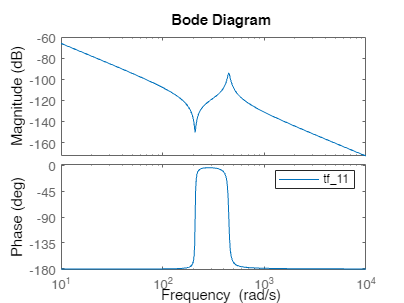



figure;
bode(tf_11)
legend

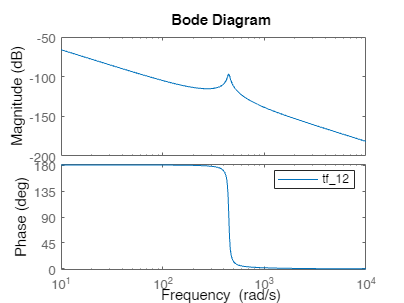


figure;
bode(tf_12)
legend

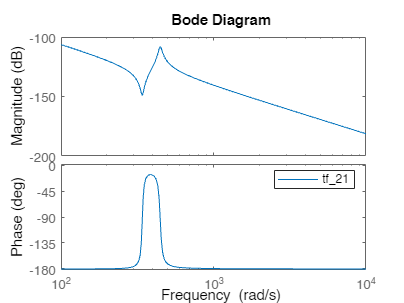


figure;
bode(tf_21)
legend

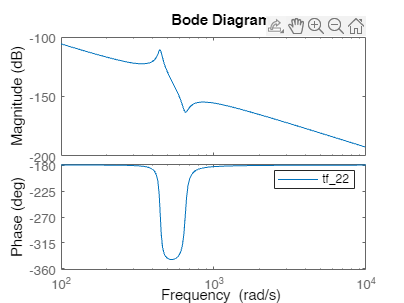


figure;
bode(tf_22)
$3legend

step_size = 20e-3;       % [m],  step size
step_time = 200e-3;   

% PID controller
f_bw = 100;              %[Hz], bandwidth of the controller
m =20;
[P, I, D, N, Kp] = PIDcode(f_bw,m);


% n = size(X);
% % Scale to max norm to bring the mass matrix to 'realistic' values
% for i=1:n(2)
%     X(:,i) = X(:,i)/max(X(:,i));
% end

%X = real(X);
% for i = 1:length(X)
%     for k = 1:length(X)
%             Fx_1(i,k) = X(i,1)*X(k,1)/(MM(1)*s^2+CC(1)*s+KK(1));
%             Fx_2(i,k) = X(i,2)*X(k,2)/(MM(2)*s^2+CC(2)*s+KK(2));
%             Fx(i,k) = Fx_1(i,k)+Fx_2(i,k);
%     end
% end

% % Transfer from Force point A to Displacement point B
% A = 1;
% B = 2;
% 
% for i=1:n(2)
%     mode(i) = tf([X(A,i)*X(B,i)],[MM(i) CC(i) KK(i)]);
% end

% % Plot response
% figure; 
% bode( mode(1)); 
% legend('mode 1');
% 
% figure; 
% bode( mode(2)); 
% legend('mode 2');
% 
% figure; 
% bode( mode(3)); 
% legend('mode 3');
% 
% figure; 
% bode( mode(4)); 
% legend('mode 4');

% sys = mode(1)+mode(2)+mode(3)+mode(4);
% 
% figure;
% stepplot(sys)
% 
% figure; 
% bode( mode(1), mode(2), mode(3), mode(4), logspace(1,5,1000)*2*pi); 
% legend;
% 
% figure; 
% bode( mode(1), 'r', mode(2), 'r', mode(3), 'r', mode(4), 'r', mode(1)+mode(2)+mode(3)+mode(4), 'k', logspace(1,5,1000)*2*pi); 
% legend('mode 1', 'mode 2', 'mode 3', 'mode 4','all modes');